**MAT 343 **

**LAB 6 (6/23/2020)**

A = imread('gauss.jpg'); 
B = double (A(: ,: ,1));
B = B /255;
[U S V] = svd(B);

**Problem 1 **

size(U), size(S), size(V)

ans =    279   279


ans =    279   211


ans =    211   211


**Problem 2 - find the rank 1 approximation of B **

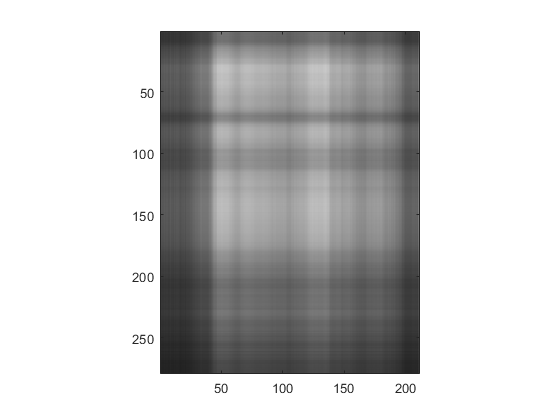

rank1 = U(:,1)*S(1,1)*V(:,1)'; 
C = zeros(size(A));
C(:,:,1) = rank1;
C(:,:,2) = rank1;
C(:,:,3) = rank1;
C = max(0,min(1,C));
image (C), axis image

**Problem 3 - rank 10 approximation **

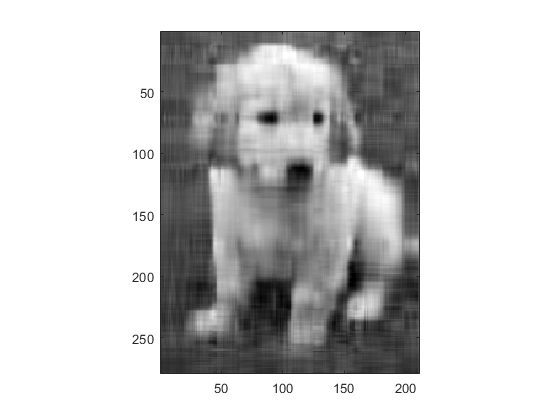

rank_selection = 10; 

rank1 = zeros(279,211); 
for i=1:rank_selection
    rank1 = rank1 + U(:,i)*S(i,i)*V(:,i)';
end

C = zeros(size(A));
C(:,:,1) = rank1;
C(:,:,2) = rank1;
C(:,:,3) = rank1;
C = max(0,min(1,C));
image (C), axis image

**Problem 4 - higher level approximations**

- Rank 30 appears to give a good approximation. I can't notice any speed differences at this level, although when I tried a rank 200 it was noticeably slower. I'm sure if I used a timing function it would show that rank 30 is extremely fast in comparison - this seems like a good trade off between speed and image quality. While the image below is grainy, it is obviously a dog. 

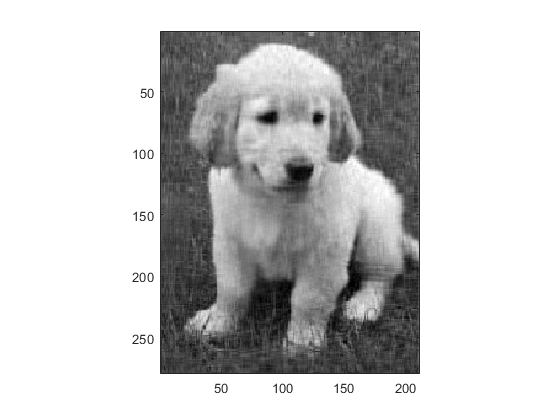

rank_selection = 30; 

rank1 = zeros(279,211); 
for i=1:rank_selection
    rank1 = rank1 + U(:,i)*S(i,i)*V(:,i)';
end

C = zeros(size(A));
C(:,:,1) = rank1;
C(:,:,2) = rank1;
C(:,:,3) = rank1;
C = max(0,min(1,C));
image (C), axis image

**Problem 5 - What rank-r approximation exactly reproduces the original picture?**

- Rank 211 exactly reproduces the original image since that is the total number of singular values we have.

**Problem 6 - How much data is needed for a rank-k approximation? **

**i) Generally: **


$$k + k*U_{m,m}+ k*V_{n,n}$$


**ii) **The compression rate represents the amount of data removed (or kept) from the original image by choosing k singular values. Thus, we can use about 75% less data than the original image.


%size of original image
279*211

ans = 58869

%size of rank 30
30+30*279+30*211

ans = 14730

compression_rate = 14730 / 58869

compression_rate = 0.2502

**Problem 7**

- using formula 6 i), I've found that $k<=\frac{\left(m*n\right)}{\left(m+n+1\right)}$ otherwise it will exceed the original image size. Solving in this example, I've found that k = 119.8961. However, because it must be an integer, and must be less than or equal to, this must be rounded down to 119. 

-  In the test case below, k > 119 results in more data than size(A) (the original image). 

m = 279;
n = 211; 

%generic formula k*(m+n+1) <= m*n 
%reduces to k <= (m*n) / (m + n + 1) 
k = (m*n) / (m+n+1)

k = 119.8961

test_k_large = 120; 

test_k_large+test_k_large*279+test_k_large*211

ans = 58920

test_k_correct = 119; 

test_k_correct+test_k_correct*279+test_k_correct*211

ans = 58429